# Esercizio di Robotica Mobile

## Blocco Mobile Robot

clear; close all; clc;

% MOBILE ROBOT


## Blocco Environment

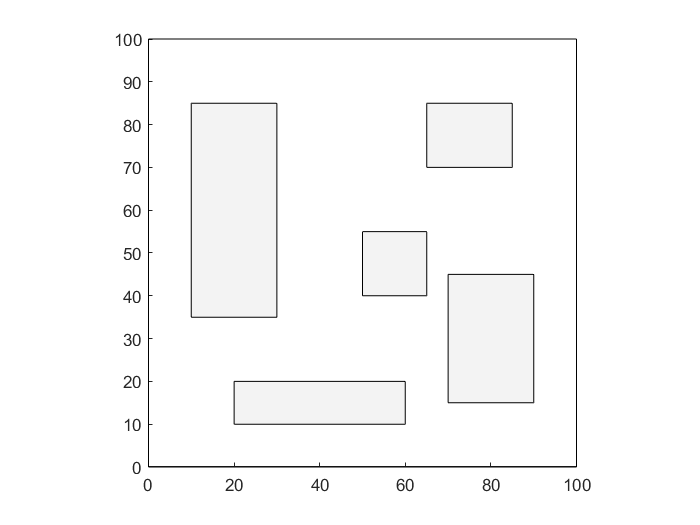

% ENVIRONMENT
stanza = zeros(100, 100);
ostacoli = zeros(5, 4);

% Muri
stanza(:,1) = 1; stanza(end,:) = 1;
stanza(1,:) = 1; stanza(:,end) = 1;

% Ostacoli
% ostacolo(i,:)=[x, y, w, h]
ostacoli(1,:) = [10 35 20 50];
ostacoli(2,:) = [20 10 40 10];
ostacoli(3,:) = [50 40 15 15];
ostacoli(4,:) = [65 70 20 15];
ostacoli(5,:) = [70 15 20 30];

% disegno la stanza
figure(1);
axis('equal'); axis([0 size(stanza, 1) 0 size(stanza, 2)]);
rectangle('Position', [0 0 size(stanza, 1) size(stanza,2)]);
for i= 1:size(ostacoli, 1)
    ostacolo = ostacoli(i,:);
    % aggiungo l'ostacolo alla stanza
    stanza(ostacolo(2):ostacolo(4)+ostacolo(2), ...
        ostacolo(1):ostacolo(3)+ostacolo(1)) = 1;
    % disegno l'ostacolo
    rectangle('Position',[ostacolo(1) ostacolo(2) ostacolo(3)...
       ostacolo(4)],'FaceColor','#f3f3f3');
end

#### Scelta di posizione iniziale, goal ed orientamento

Seguire le istruzioni presenti nella command window per procedere.

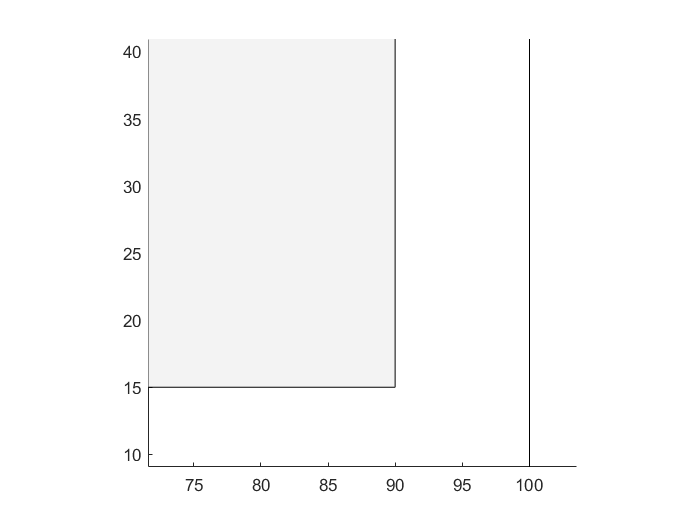

prompt = "Inserire i valori del punto di partenza 'SP=[x,y]', " + ...
    "del goal 'G=[x,y]' e dell'orientamento " + newline + ...
    "finale 'thetaG=x' (espresso in radianti)" + newline + " > SP = ";
SP = [5 5]; %input(prompt);
G = [95 95];%input(" > G = ");
thetaG = pi/2;%input(" > thetaG = ");

% disegno la stanza con il punto di partenza ed il goal
figure(2); hold on;
axis('equal'); axis([0 size(stanza, 1) 0 size(stanza, 2)]);
rectangle('Position', [0 0 size(stanza, 1) size(stanza,2)]);
for i= 1:size(ostacoli, 1)
    ostacolo = ostacoli(i,:);
    rectangle('Position',[ostacolo(1) ostacolo(2) ...
        ostacolo(3) ostacolo(4)],'FaceColor','#f3f3f3');
end
plot(SP(1),SP(2),'*'); plot(G(1),G(2),'*');

## Blocco Planner

A questo punto si conoscono sia l'ambiente che i dati in input al sistema, quindi si può procedere con la progettazzione delle traiettorie.

Seguire le istruzioni presenti nella command window per procedere.

prompt = "Inserire il numero relativo alla tecnica che si vuole utilizzare:" + newline + ...
    " 1) Artificial Potential Fields" + newline + " 2) Discrete Potential Fields" + newline + ...
    " 3) Voronoi Diagrams" + newline + " 4) Visibility Graphs" + newline + "> ";
scelta_planner = 1; %input(prompt);

% Artificial Potential Fields
if scelta_planner == 1
    [path]=Artificial_Potential_Fields(SP,G,stanza, ostacoli);
end